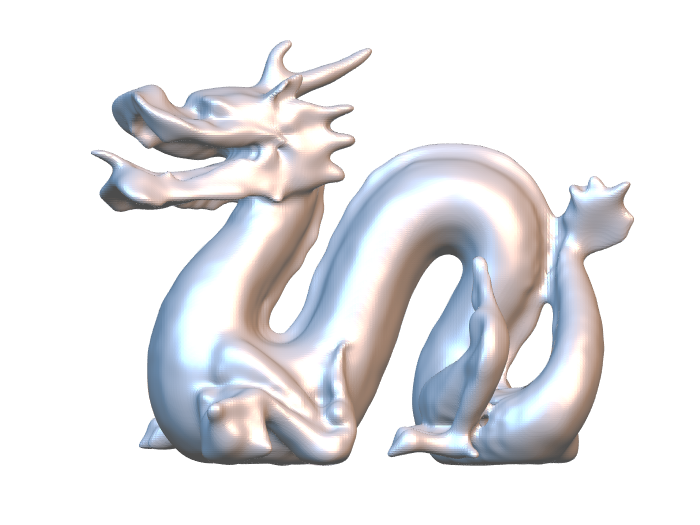

res = 200;
%bunny
% minPoint = [-0.0946 0.0333 -0.0618];
% maxPoint = [0.0610 0.1873 0.0588];
%dragon
minPoint = [-0.090 0.052 -0.052];
maxPoint = [0.098 0.199 0.043];
%sphere
% minPoint = [-1 -1 -1];
% maxPoint = [1 1 1];
%buddha
% minPoint=[-0.0461 0.0498 -0.0474];
% maxPoint=[0.0352 0.2478 0.0340];
%horse
% minPoint=[-0.3623 -0.3020 -0.1660];
% maxPoint=[0.3623 0.3020 0.1660];
%goldfish
% minPoint=[-5.0537 -9.7012 -12.8447];
% maxPoint=[5.0759 8.1533 13.9778];
%hand
% minPoint=[0.093983 0.186629 0.405895];
% maxPoint=[6.721100 4.829110 2.681050];
%Armadillo
% minPoint=[-63.5001 -54.0676 -57.7145];
% maxPoint=[63.3454 97.0804 57.7140];
%Bimba
% minPoint=[-8.663986 -10.000000 -7.216264];
% maxPoint=[8.663986 10.000000 7.216264];
%Torus
%  minPoint=[-0.588880 -0.588886 -0.091571];
%  maxPoint=[0.588464 0.588887 0.091574];
 %8
%  minPoint=[-0.588514 -1.238486 -0.108438];
%  maxPoint=[0.588068 0.588487 0.108437];
%Old  man
% minPoint=[-5.907623 -9.872915 -7.504540];
% maxPoint=[5.888952 9.996798 7.475170];
%vaselion
% minPoint=[-0.3030 -0.5000 -0.3691];
% maxPoint=[0.3030 0.5000 0.3691];
%dinosaur
% minPoint=[-0.0194,-0.0579,-0.0490];
% maxPoint=[0.0194,0.0579,0.0490];
%cow
% minPoint=[-0.657 -0.591 -0.286];
% maxPoint=[0.975 0.472 0.286];
%dog
% minPoint=[-0.757 -1.000 -0.855];
% maxPoint=[0.757 1.000 0.855];
%Igea
% minPoint=[-6.956340 -9.970630 -9.997980];
% maxPoint=[6.944840 9.972520 9.998780];
%teddy
% minPoint=[-0.658921 -0.716940 -0.360366];
% maxPoint=[0.650144 0.941371 0.570984];
xlim = [minPoint(1) maxPoint(1)];
x = xlim(1):(xlim(2)-xlim(1))/res:xlim(2);
ylim = [minPoint(2) maxPoint(2)];
y = ylim(1):(ylim(2)-ylim(1))/res:ylim(2);
zlim = [minPoint(3) maxPoint(3)];
z = zlim(1):(zlim(2)-zlim(1))/res:zlim(2);
[MX,MY,MZ] = meshgrid(x,y,z);
V = reshape(V,res+1,res+1,res+1);
h = figure;
ax = axes('Parent',h);
ax.YAxis.Visible = 'off';
ax.XAxis.Visible = 'off';
ax.ZAxis.Visible = 'off';
p = patch(isosurface(MX,MY,MZ,V,0));
isonormals(MX,MY,MZ,V,p);
view(2);
% p.FaceColor = [0.9 0.9 0.8];
p.FaceColor = 'white';
p.EdgeColor = 'none';
daspect([1 1 1]);
axis tight
leftlgt = camlight('left');
leftlgt.Color = [60 128 200]/255;
% leftlgt.Color = [20 60 255]/255;
rightlgt = camlight('right');
rightlgt.Color = [200 126 80]/255;
%rightlgt.Color = [180 120 80]/255;
material default;
hold on;
%ptCloud.Intensity = ApproxArgs;
%pcshow(ptCloud);
% view(2)
% axis normal;
  hold off;

%ptCloud = pcread('bunny_453.ply');

%figure;
%pcshow(ptCloud);